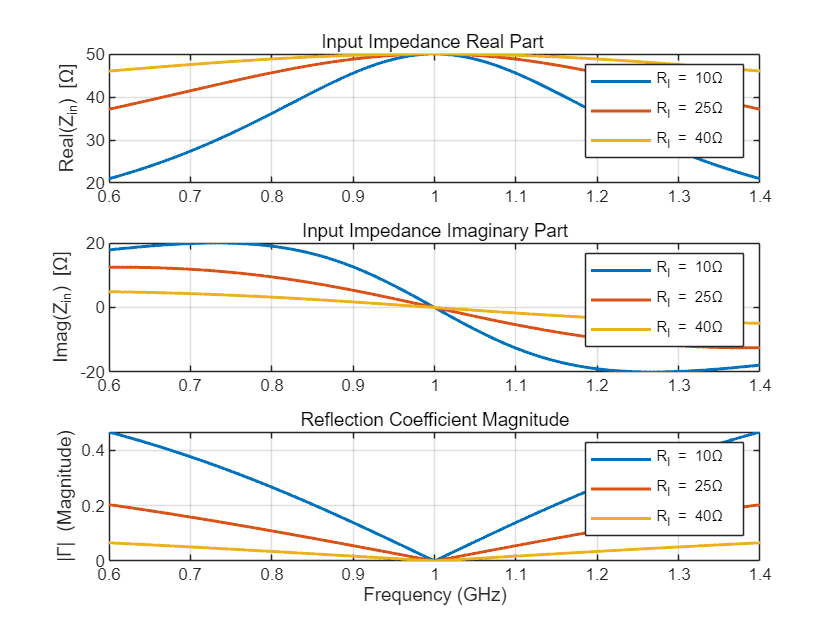

clc;
clear;
close all;

Z0 = 50;                    % Characteristic impedance of main line (Ohms)
f_start = 0.6e9;            % Start Frequency (Hz)
f_stop = 1.4e9;             % Stop Frequency (Hz)
f_step = 1e6;               % Step interval (1 MHz)
freq = f_start:f_step:f_stop; % Frequency vector


f0 = (f_start + f_stop) / 2; 
Rl_cases = [10, 25, 40];
figure('Color', 'w', 'Name', 'Quarter Wave Transformer Analysis');


for i = 1:length(Rl_cases)
    Rl = Rl_cases(i);
    
    ZT = sqrt(Z0 * Rl);
    
    theta = (pi/2) * (freq / f0);
    
    numerator = Rl + 1j * ZT .* tan(theta);
    denominator = ZT + 1j * Rl .* tan(theta);
    Zin = ZT .* (numerator ./ denominator);
    
    Gamma = (Zin - Z0) ./ (Zin + Z0);
    
    subplot(3, 1, 1);
    plot(freq/1e9, real(Zin), 'LineWidth', 1.5); hold on;
    ylabel('Real(Z_{in}) [\Omega]');
    title(['Input Impedance Real Part ']);
    grid on;

    subplot(3, 1, 2);
    plot(freq/1e9, imag(Zin), 'LineWidth', 1.5); hold on;
    ylabel('Imag(Z_{in}) [\Omega]');
    title('Input Impedance Imaginary Part');
    grid on;
    
    subplot(3, 1, 3);
    plot(freq/1e9, abs(Gamma), 'LineWidth', 1.5); hold on;
    ylabel('|\Gamma| (Magnitude)');
    xlabel('Frequency (GHz)');
    title('Reflection Coefficient Magnitude');
    grid on;
end

subplot(3, 1, 1); legend('R_l = 10\Omega', 'R_l = 25\Omega', 'R_l = 40\Omega');
subplot(3, 1, 2); legend('R_l = 10\Omega', 'R_l = 25\Omega', 'R_l = 40\Omega');
subplot(3, 1, 3); legend('R_l = 10\Omega', 'R_l = 25\Omega', 'R_l = 40\Omega');

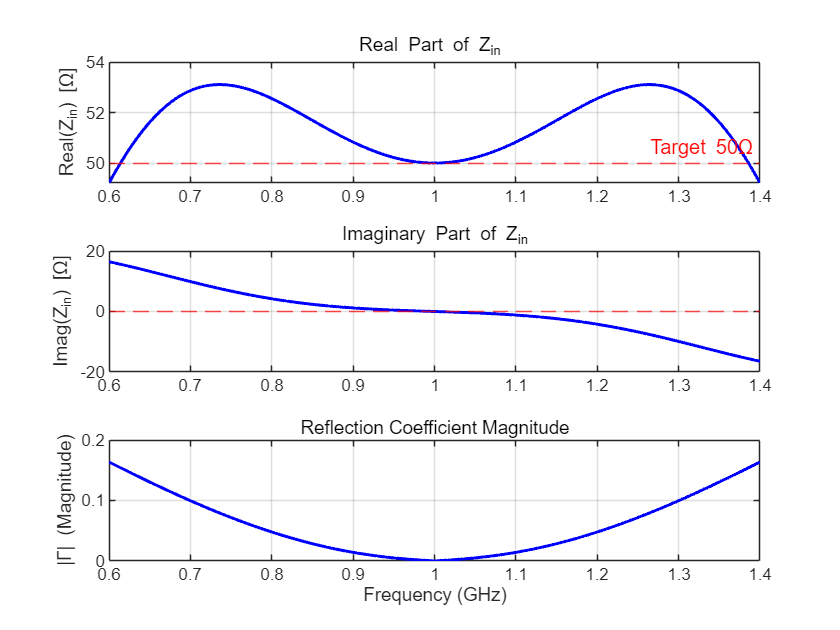

clc;
clear;
close all;

Z0 = 50;                    % Characteristic impedance of main line (Ohms)
Rl = 20;                    % Load Resistance (Ohms)
R_mid = 30;                 % Intermediate impedance target (Ohms)

f_start = 0.6e9;            % Start Frequency
f_stop = 1.4e9;             % Stop Frequency
f_step = 1e6;               % Step interval
freq = f_start:f_step:f_stop; 

f0 = (f_start + f_stop) / 2; 

ZT1 = sqrt(Rl * R_mid);

ZT2 = sqrt(R_mid * Z0);

theta = (pi/2) * (freq / f0);

numerator1 = Rl + 1j * ZT1 .* tan(theta);
denominator1 = ZT1 + 1j * Rl .* tan(theta);
Zin1 = ZT1 .* (numerator1 ./ denominator1);

numerator2 = Zin1 + 1j * ZT2 .* tan(theta);
denominator2 = ZT2 + 1j * Zin1 .* tan(theta);
Zin_total = ZT2 .* (numerator2 ./ denominator2);


Gamma = (Zin_total - Z0) ./ (Zin_total + Z0);


figure('Color', 'w', 'Name', 'Double-Section Transformer');

subplot(3, 1, 1);
plot(freq/1e9, real(Zin_total), 'b', 'LineWidth', 1.5);
ylabel('Real(Z_{in}) [\Omega]');
title(['Real Part of Z_{in} ']);
grid on; yline(50, '--r', 'Target 50\Omega'); % Mark target

subplot(3, 1, 2);
plot(freq/1e9, imag(Zin_total), 'b', 'LineWidth', 1.5);
ylabel('Imag(Z_{in}) [\Omega]');
title('Imaginary Part of Z_{in}');
grid on; yline(0, '--r'); % Mark zero

subplot(3, 1, 3);
plot(freq/1e9, abs(Gamma), 'b', 'LineWidth', 1.5);
ylabel('|\Gamma| (Magnitude)');
xlabel('Frequency (GHz)');
title('Reflection Coefficient Magnitude');
grid on;


fprintf('Calculated Transformer Impedances:\n');

Calculated Transformer Impedances:


fprintf('Section 1 (Load Side) ZT1: %.2f Ohms\n', ZT1);

Section 1 (Load Side) ZT1: 24.49 Ohms


fprintf('Section 2 (Source Side) ZT2: %.2f Ohms\n', ZT2);

Section 2 (Source Side) ZT2: 38.73 Ohms
